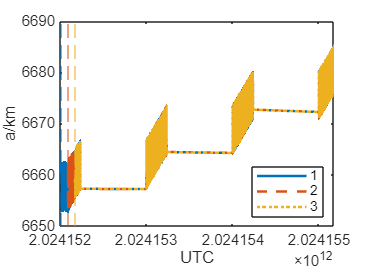

res1=importdata('MEME_799500932_STARLINK-31920_1520146_Operational_1401414420_UNCLASSIFIED_eles.txt');
res2=importdata('MEME_799500932_STARLINK-31920_1520915_Operational_1401441360_UNCLASSIFIED_eles.txt');
res3=importdata('MEME_799500932_STARLINK-31920_1521750_Operational_1401472260_UNCLASSIFIED_eles.txt');
time_1=2024152021958;
time_2=2024152103430;
time_3=2024152182825;
figure
plot(res1(:,1),res1(:,2),'-',res2(:,1),res2(:,2),'--',res3(:,1),res3(:,2),':','LineWidth', 1.5);
hold on
xline(time_1, '--',"Color","#0072BD")
xline(time_2, '--',"Color","#D95319")
xline(time_3, '--',"Color","#EDB120")
legend('1', '2', '3', 'Location', 'Best');
xlabel('UTC');
ylabel('a/km');

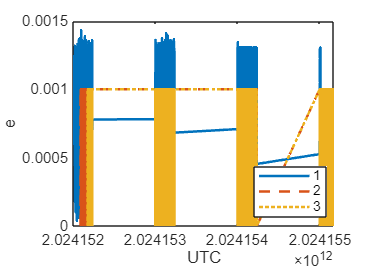

% title('三段拼接半长轴变化');
figure
plot(res1(:,1),res1(:,3),'-',res2(:,1),res2(:,3),'--',res3(:,1),res3(:,3),':','LineWidth', 1.5);
legend('1', '2', '3', 'Location', 'Best');
ax = gca;
ax.YAxis.Exponent = 0;
xlabel('UTC');
ylabel('e');

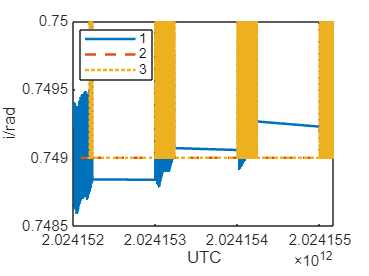

% title('三段拼接偏心率变化');
plot(res1(:,1),res1(:,4),'-',res2(:,1),res2(:,4),'--',res3(:,1),res3(:,4),':','LineWidth', 1.5);
legend('1', '2', '3', 'Location', 'Best');
xlabel('UTC');
ylabel('i/rad');

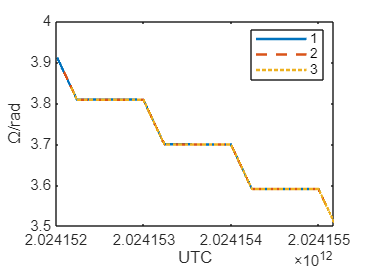

% title('三段拼接倾角变化');
plot(res1(:,1),res1(:,5),'-',res2(:,1),res2(:,5),'--',res3(:,1),res3(:,5),':','LineWidth', 1.5);
legend('1', '2', '3', 'Location', 'Best');
xlabel('UTC');
ylabel('\Omega/rad');

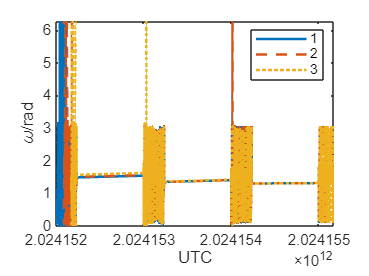

% title('三段拼接升交点经度变化');
plot(res1(:,1),res1(:,6),'-',res2(:,1),res2(:,6),'--',res3(:,1),res3(:,6),':','LineWidth', 1.5);
legend('1', '2', '3', 'Location', 'Best');
xlabel('UTC');
ylabel('\omega/rad');

% title('三段拼接近地点角距变化');

% 三段对比
compare=[res1(965:end,1) res2(516:3872,2:end)-res1(965:end,2:end) res3(1:3357,2:end)-res1(965:end,2:end)]

compare = 1.0e+12 *

    2.0242   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    2.0242   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    2.0242   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    2.0242   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    2.0242   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    2.0242   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    2.0242   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    2.0242   -0.0000    0.0000    0.0000   -0.0000   -0.0000  

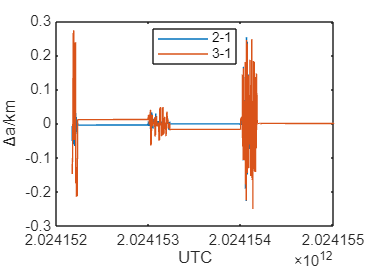

% 半长轴
plot(compare(:,1),compare(:,2),compare(:,1),compare(:,8))
legend('2-1', '3-1', 'Location', 'Best');
xlabel('UTC');
ylabel('\Deltaa/km');

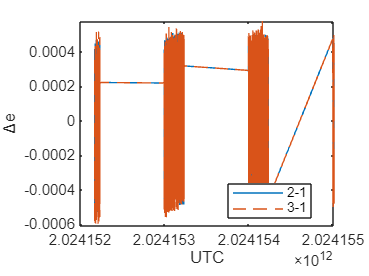

% 偏心率
plot(compare(:,1),compare(:,3),compare(:,1),compare(:,9),'--')
legend('2-1', '3-1', 'Location', 'Best');
xlabel('UTC');
ylabel('\Deltae');

ax = gca;
ax.YAxis.Exponent = 0;